close all; clear; clc;

# Test Name

**file name**: CP_vs_CT_plots.mlx

**keywords:** 

**date of test:** date

**file created by:** date, Edmonds

**last updated on:** YYYYMMDD

**primary purpose:** 

**primary input and output variables: **

calculated/not measured from test stand- motor radius and rho. 

measured from test stand- time, ESC us, Torque, Thrust, input voltage, input current, rotational speed (omega), input power, output power, efficiencies (motor, prop, overall), temp probe (by motor)

**functions:** 

**Notes:** 

## Input Variables

Use Atmospheric Condition Calculator to calculate air density

P80 = xlsread('P80.xlsx');
turn = xlsread('Turnigy.xlsx');
mega = xlsread('MEGA.xlsx');
KDE = xlsread('KDE.xlsx');
mini = xlsread('Mini.xlsx');

## KDE

Q_KDE = KDE(:,10);                          % [ft.lbf]
T_KDE = KDE(:,11);                          % [lbf]
rpm_KDE = KDE(:,14);              % [RPM]
% convert to RPM for plotting purposes
rad_KDE = rpm_KDE .* (pi/30);                       % [rad/sec]
P_out_W_KDE = KDE(:,16);                   % [Watts]
% convert to [ft.lbf/sec]
P_out_KDE = P_out_W_KDE .* 0.7478;                  % [ft.lbf/sec] 
area_KDE = KDE(:,6);
diameter_KDE = KDE(:,5);
p_KDE = KDE(:,24);

C_T_KDE = T_KDE ./ (p_KDE .* area_KDE .* (rad_KDE .* (diameter_KDE ./ 2)).^2);
C_P_KDE = P_out_KDE ./ (p_KDE .* area_KDE .* (rad_KDE .* (diameter_KDE ./ 2)).^3);
C_Q_KDE = Q_KDE ./ (p_KDE .* area_KDE .* (rad_KDE .* (diameter_KDE ./ 2)).^(2) .* (diameter_KDE / 2));

## MEGA

Q_mega = mega(:,10);                          % [ft.lbf]
T_mega = mega(:,11);                          % [lbf]
rpm_mega = mega(:,14);              % [RPM]
% convert to RPM for plotting purposes
rad_mega = rpm_mega .* (pi/30);                       % [rad/sec]
P_out_W_mega = mega(:,16);                   % [Watts]
% convert to [ft.lbf/sec]
P_out_mega = P_out_W_mega .* 0.7478;                  % [ft.lbf/sec] 
area_mega = mega(:,6);
diameter_mega = mega(:,5);
p_mega = mega(:,24);

C_T_mega = T_mega ./ (p_mega .* area_mega .* (rad_mega .* (diameter_mega ./ 2)).^2);
C_P_mega = P_out_mega ./ (p_mega .* area_mega .* (rad_mega .* (diameter_mega ./ 2)).^3);
C_Q_mega = Q_mega ./ (p_mega .* area_mega .* (rad_mega .* (diameter_mega ./ 2)).^(2) .* (diameter_mega / 2));

## Turnigy

Q_turn = turn(:,10);                          % [ft.lbf]
T_turn = turn(:,11);                          % [lbf]
rpm_turn = turn(:,14);              % [RPM]
% convert to RPM for plotting purposes
rad_turn = rpm_turn .* (pi/30);                       % [rad/sec]
P_out_W_turn = turn(:,16);                   % [Watts]
% convert to [ft.lbf/sec]
P_out_turn = P_out_W_turn .* 0.7478;                  % [ft.lbf/sec] 
area_turn = turn(:,6);
diameter_turn = turn(:,5);
p_turn = turn(:,24);

C_T_turn = T_turn ./ (p_turn .* area_turn .* (rad_turn .* (diameter_turn ./ 2)).^2);
C_P_turn = P_out_turn ./ (p_turn .* area_turn .* (rad_turn .* (diameter_turn ./ 2)).^3);
C_Q_turn = Q_turn ./ (p_turn .* area_turn .* (rad_turn .* (diameter_turn ./ 2)).^(2) .* (diameter_turn / 2));

## P80

Q_P80 = P80(:,10);                          % [ft.lbf]
T_P80 = P80(:,11);                          % [lbf]
rpm_P80 = P80(:,14);              % [RPM]
% convert to RPM for plotting purposes
rad_P80 = rpm_P80 .* (pi/30);                       % [rad/sec]
P_out_W_P80 = P80(:,16);                   % [Watts]
% convert to [ft.lbf/sec]
P_out_P80 = P_out_W_P80 .* 0.7478;                  % [ft.lbf/sec] 
area_P80 = P80(:,6);
diameter_P80 = P80(:,5);
p_P80 = P80(:,24);

C_T_P80 = T_P80 ./ (p_P80 .* area_P80 .* (rad_P80 .* (diameter_P80 ./ 2)).^2);
C_P_P80 = P_out_P80 ./ (p_P80 .* area_P80 .* (rad_P80 .* (diameter_P80 ./ 2)).^3);
C_Q_P80 = Q_P80 ./ (p_P80 .* area_P80 .* (rad_P80 .* (diameter_P80 ./ 2)).^(2) .* (diameter_P80 / 2));

## Mini

Q_mini = mini(:,10);                          % [ft.lbf]
T_mini = mini(:,11);                          % [lbf]
rpm_mini = mini(:,14);              % [RPM]
% convert to RPM for plotting purposes
rad_mini = rpm_mini .* (pi/30);                       % [rad/sec]
P_out_W_mini = mini(:,16);                   % [Watts]
% convert to [ft.lbf/sec]
P_out_mini = P_out_W_mini .* 0.7478;                  % [ft.lbf/sec] 
area_mini = mini(:,6);
diameter_mini = mini(:,5);
p_min = mini(:,24);

C_T_mini = T_mini ./ (p_min .* area_mini .* (rad_mini .* (diameter_mini ./ 2)).^2);
C_P_mini = P_out_mini ./ (p_min .* area_mini .* (rad_mini .* (diameter_mini ./ 2)).^3);
C_Q_mini = Q_mini ./ (p_min .* area_mini .* (rad_mini .* (diameter_mini ./ 2)).^(2) .* (diameter_mini / 2));

## Comparing Data to Momentum Theory

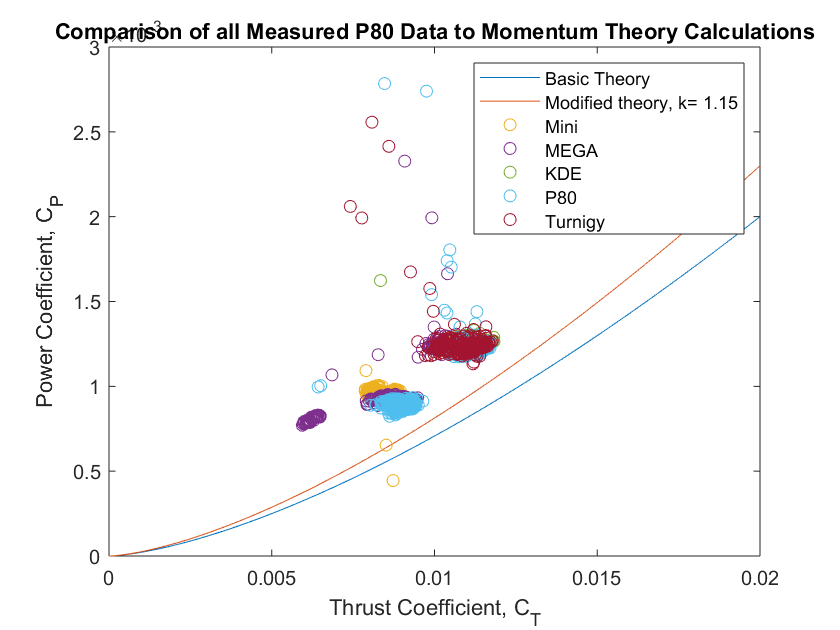

k = 1.15;
C_T_theory = linspace(0, 0.02, 1000);
C_P_theory = C_T_theory .^(3/2) ./ sqrt(2);
C_Pi = k .* (C_T_theory .^(3/2) ./ sqrt(2));

figure(100)
plot(C_T_theory, C_P_theory, C_T_theory, C_Pi,...
    C_T_mini, C_P_mini, 'o',...
    C_T_mega, C_P_mega, 'o',...
    C_T_KDE, C_P_KDE, 'o',...
    C_T_P80, C_P_P80, 'o',...
    C_T_turn, C_P_turn, 'o');
title('Comparison of all Measured P80 Data to Momentum Theory Calculations');
xlabel('Thrust Coefficient, C_T'); ylabel('Power Coefficient, C_P');
legend('Basic Theory', 'Modified theory, k= 1.15', 'Mini',...
    'MEGA', 'KDE', 'P80', 'Turnigy');
xlim([0 0.02]); ylim([0 0.003]);